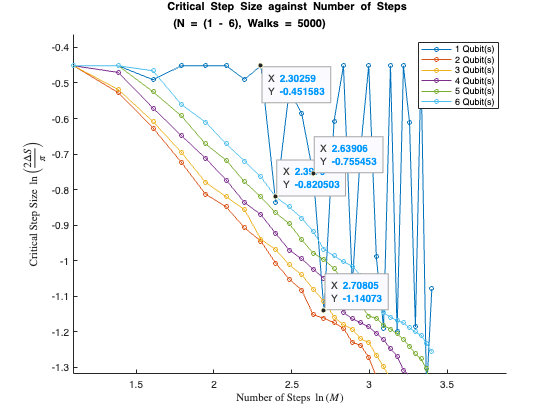

Number_of_Qubits =  6;
Number_of_Walks = 5e3;
Number_of_Steps = 30; 

Step_Size_Resolution = 1e-1;
Bisection_Interval_Size = 1e-10;

Critical_Step_Data_Collection_Function(Number_of_Qubits, Number_of_Walks, Number_of_Steps, Step_Size_Resolution, Bisection_Interval_Size);


function Data = Critical_Step_Data_Collection_Function(Number_of_Qubits, Number_of_Walks, Number_of_Steps, Step_Size_Resolution, Interval_Size)

figure;
hold on;

Critical_Step_Size = zeros(Number_of_Qubits,Number_of_Steps);
Data = zeros(2,length(0:Step_Size_Resolution:1));

for N = 1:Number_of_Qubits

    Precision = pi*0.5 - acos(1/sqrt(2^N));

    for M = 1:Number_of_Steps

        j=1;
        
        for S = 0:Step_Size_Resolution:1
            
            Data(1,j) = S;
            Data(2,j) = Random_Walk_Algorithm(N, M, Number_of_Walks, S);
        
            j=j+1;
        end
    
        Critical_Step_Size(N,M) = Bisection_Function(Data, Interval_Size, Precision); 
        
    end

    plot(log(1:Number_of_Steps), log((2/pi)*Critical_Step_Size(N,:)), '-o', 'LineWidth', 1, 'MarkerSize', 4, 'DisplayName', sprintf('%d Qubit(s)', N));
end

    xlabel('Number of Steps $ \ln \left( M \right) $', 'Interpreter', 'latex');
    xlim([log(3),log(Number_of_Steps)])
    ylabel('Critical Step Size $ \ln \left( \frac{2 \Delta S}{\pi} \right) $', 'Interpreter', 'latex');
    %yline(Precision, 'r--', 'LineWidth', 1, 'DisplayName','Precision'); 
    title(sprintf('Critical Step Size against Number of Steps \\newline (N = (1 - %d), Walks = %d)', Number_of_Qubits, Number_of_Walks));
    legend;

hold off;
end

%{
function Data = Qubit_Ranges_Data_Collection_Function(Number_of_Qubits, Number_of_Walks, Number_of_Steps, Step_Size_Resolution, Interval_Size)
 
figure;
hold on;

for Number_of_Qubits = 1:Number_of_Qubits

    Precision = pi*0.5 - acos(1/sqrt(2^Number_of_Qubits));

    Data = zeros(2,length(0:Step_Size_Resolution:1));
    j=1;
    
    for i = 0:Step_Size_Resolution:1
        
        Data(1,j) = i;
        Data(2,j) = Random_Walk_Algorithm(Number_of_Qubits, Number_of_Steps, Number_of_Walks, i);
    
        j=j+1;
    end 
    
    plot(Data(1,:), Data(2,:), '-o', 'LineWidth', 1, 'MarkerSize', 4, 'DisplayName', sprintf('%d Qubit(s)', Number_of_Qubits));
    xlabel('Step Size / $ \Delta S $', 'Interpreter', 'latex');
    ylabel('$ 1 - \frac{2}{\pi}\langle d( \psi_0,\psi_f ) \rangle $', 'Interpreter', 'latex');
    %yline(Precision, 'r--', 'LineWidth', 1, 'DisplayName','Precision'); 
    title(sprintf('Expected Walk Distance against Step Size \\newline (N = 1 - %d, Walks = %d, Number of Steps = %d)', Number_of_Qubits, Number_of_Walks, Number_of_Steps));
    legend;

    Critical_Step_Size = Bisection_Function(Data, Interval_Size, Precision) 

    
end

hold off;
end
%}

function RWA = Random_Walk_Algorithm(Number_of_Qubits, Number_of_Steps, Number_of_Walks, Step_Size)

    Final_Distances = zeros(1,Number_of_Walks);

    Dimensions = 2^Number_of_Qubits;
    Component_Volume = Number_of_Walks*Number_of_Steps;
    
    Pole_Vector = zeros(Dimensions, 1);
    Pole_Vector(1) = 1; 
    
     Vector_Database= randn(Dimensions, Component_Volume)+1i*randn(Dimensions, Component_Volume);
    
    for i = 1:Number_of_Walks
     
            Vector = Pole_Vector; 
        
                    for j = 1:Number_of_Steps

                        Selected_Vector = Vector_Database(:,j+(i-1)*Number_of_Steps);
               
                        Normalised_Vector = Selected_Vector; 
                        Projection = (Normalised_Vector - dot(Normalised_Vector,Vector)*Vector)/norm((Normalised_Vector - dot(Normalised_Vector,Vector)*Vector));
                
                        Vector = cos(Step_Size)*Vector + sin(Step_Size)*Projection;
                    end 

              Final_Distances(:,i) = Fubini_Study_Distance(Pole_Vector, Vector);
    end 

    RWA = pi*0.5 - abs(mean(Final_Distances));
end 

function Root = Bisection_Function(Data, Tolerance, Precision)

    Lower_Bound = 0;
    Upper_Bound = 1;

    Interpolation = @(x_val) interp1(Data(1,:), Data(2,:), x_val, 'linear', 'extrap');

    while (Upper_Bound - Lower_Bound) / 2 >= Tolerance
        
        Mid_Point = (Lower_Bound + Upper_Bound) / 2;
 
        Lower_Bound_Interpolation = Interpolation(Lower_Bound);
        Mid_Point_Interpolation = Interpolation(Mid_Point);
        
        if abs(Mid_Point_Interpolation - Precision) < Tolerance
            Root = Mid_Point;
            return;
        end
 
        if (Lower_Bound_Interpolation - Precision) * (Mid_Point_Interpolation - Precision) < 0
            Upper_Bound = Mid_Point;  
        else
            Lower_Bound = Mid_Point;  
        end
    end
    
    Root = (Lower_Bound + Upper_Bound) / 2;

end


function FBS = Fubini_Study_Distance(Vector_1, Vector_2)

    FBS = acos(abs(dot(Vector_1,Vector_2)));
end